clear all

syms cc
taylor(exp(cc))

$$ans = \frac{{\mathrm{cc}}^{5}}{120}+\frac{{\mathrm{cc}}^{4}}{24}+\frac{{\mathrm{cc}}^{3}}{6}+\frac{{\mathrm{cc}}^{2}}{2}+\mathrm{cc}+1$$

taylor(sin(cc))

$$ans = \frac{{\mathrm{cc}}^{5}}{120}-\frac{{\mathrm{cc}}^{3}}{6}+\mathrm{cc}$$


taylor(exp(cc)) + taylor(sin(cc))+3*taylor(cos(cc))

$$ans = \frac{{\mathrm{cc}}^{5}}{60}+\frac{{\mathrm{cc}}^{4}}{6}-{\mathrm{cc}}^{2}+2\,\mathrm{cc}+4$$

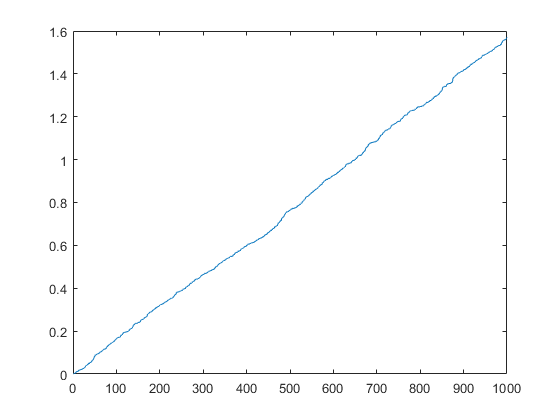

input = 2*rand(1000,1)-1;
output = sin(exp(input)+sin(10*input).^2+3*cos(3*input)+0.3*rand(1000,1));

% output= (output-mean(output))/std(output);

% input = mat2gray(input)*pi/4;
% output = mat2gray(output)*pi/4;

input = normalize(input, 'range')*pi/2;
output = normalize(output, 'range')*pi/2;

plot(sort(input))


datasize = length(input);
batchsize = 100;
minis = datasize/batchsize

minis = 10

decay =1

decay = 1

alpha = 0.00001

alpha = 1.0000e-05

alfa = 0.001

alfa = 1.0000e-03

beta= 0

beta = 0

n=3

n = 3

eps = 10^-2

eps = 0.0100


V=zeros(batchsize,1) %momentum

V =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


B = 0.5

B = 0.5000

V1=0;
V2=0;
V3=0;
V4=0;

X = normalize(rand(3,3))/10;
ex= [0:n];

w1= X(:,1);
w2= X(:,2);
w3= X(:,3);


err(1:2)=1;
alfa = 0.001

alfa = 1.0000e-03

% number of epochs
for i = 2:1000

% Learning rate
alpha=alfa; %/(eps+err(i));  
alphas(i)=alpha;    
    
%divide data in batches
indexes= randperm(1000);
batchinput = reshape(input(indexes), [batchsize minis]);    
batchoutput = reshape(output(indexes), [batchsize minis]);

    for j = 1:minis
a1 = batchinput(:,j);
a2 = ([ones(batchsize,1) sin(a1) cos(a1)]*w1);
a3 = ([ones(batchsize,1) sin(a2) cos(a2)]*w2);
a4 = ([ones(batchsize,1) sin(a3) cos(a3)]*w3);
% a4 = ([sin(a3) cos(a3)]*w3);

% meansa2(j) = mean(a2);
% meansa3(j) = mean(a3);
% stdsa2(j) = std(a2);
% stdsa3(j) = std(a3);
% a4 = a3.^ex*w3;
% % d4 = a4-batchoutput(:,j);
% d3 = d4 .* [zeros(batchsize,1) ones(batchsize,1) 2*a3 3*a3.^2 4*a3.^3] *w3;

d4 = a4-batchoutput(:,j);
d3 = d4 .* [zeros(batchsize,1) cos(a3) -sin(a3)] *w3;
d2 = d3 .* [zeros(batchsize,1) cos(a2) -sin(a2)] *w2;
d1 = d2 .* [zeros(batchsize,1) cos(a1) -sin(a1)] *w1;

% D = [d2;d1]

V4=B*V4 + (1-B)*d4;
V3=B*V3 + (1-B)*d3;
V2=B*V2 + (1-B)*d2;
V1=B*V1 + (1-B)*d1;

% w3 = pinv([sin(a3) cos(a3)])*(a4-alpha*V4)*decay;
w3 = pinv([ones(batchsize,1) sin(a3) cos(a3)])*(a4-alpha*V4)*decay;
w2 = pinv([ones(batchsize,1) sin(a2) cos(a2)])*(a3-alpha*V3)*decay;
w1 = pinv([ones(batchsize,1) sin(a1) cos(a1)])*(a2-alpha*(V2))*decay;

    end

    
a1=input;
a2 = ([ones(datasize,1) sin(a1) cos(a1)]*w1);
a3 = ([ones(datasize,1) sin(a2) cos(a2)]*w2);
a4 = ([ones(datasize,1) sin(a3) cos(a3)]*w3);

err(i+1) = norm(a3-output)/norm(output);

if (err(i)<0.0001) %||(abs(err(i)-err(i-1))<0.0000001)
    disp("iterations: " + i)
     disp("error: " + err(i))
    break;
end 
end
disp("error: " + err(i))

error: 12885.0044


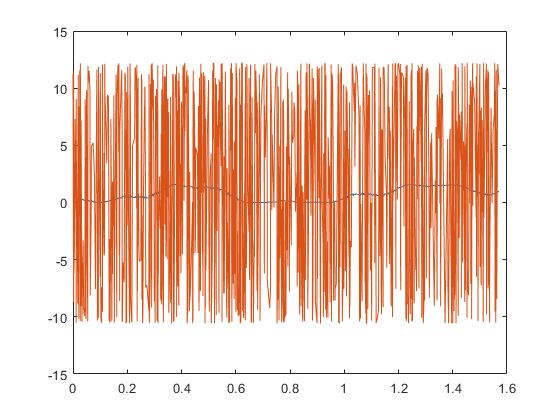



[B1,I] = sort(input);
B2 = output(I);

plot([B1 B1],[B2 a4(I)])

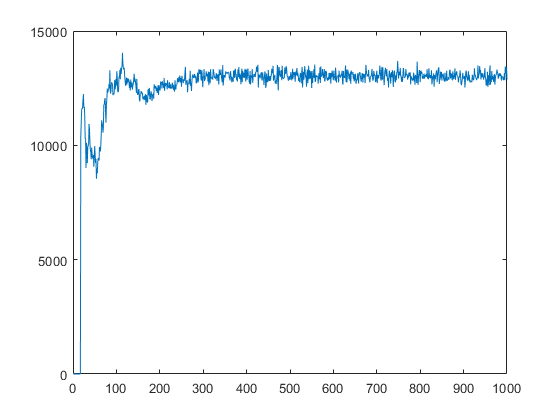


plot(err(1:i))

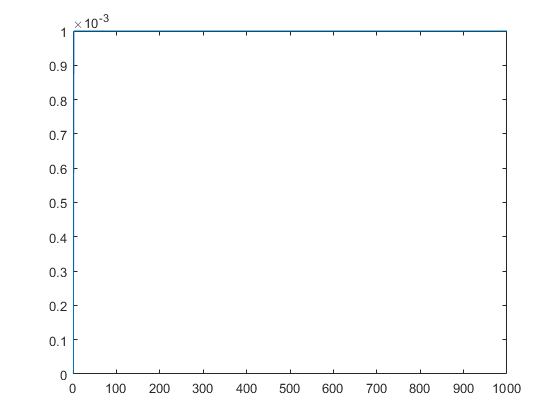

plot(alphas(1:i))


w1

w1 = 	1.0e+07 *

   -8.7273
    5.0783
    5.3717


w2

w2 = 	1.0e+03 *

   -9.4233
    3.0890
    9.5475


w3

w3 =     0.8085
    0.0957
  -11.3843



ex=0:3

ex =      0     1     2     3


% zeros(1000,1) ones(1000,1)

w1 =  rand(4,1)

w1 =     0.2896
    0.9387
    0.8231
    0.7355


w2 =  rand(4,1)

w2 =     0.5230
    0.4771
    0.8790
    0.8972



a1 = input(1:200)

a1 =     1.2671
    1.0482
    0.3467
    1.3220
    1.0612
    0.0882
    1.0823
    0.6652
    0.1148
    0.8618



a2 = a1.^ex*w1 

a2 =     4.2966
    3.0251
    0.7446
    4.6686
    3.0915
    0.3792
    3.2021
    1.4948
    0.4093
    2.1805



a3 = a2.^ex*w2

a3 =    89.9635
   34.8464
    1.7359
  113.2008
   36.9063
    0.8793
   40.5194
    6.1968
    0.9270
   15.0446




d3 = a3-output(1:200)

d3 =    88.4076
   34.1441
    0.3293
  111.7447
   36.2081
    0.8732
   39.7493
    6.1960
    0.9186
   15.0331


d2 = d3 .* [zeros(200,1) ones(200,1) 2*a2 3*a2.^2] *w2

d2 = 	1.0e+04 *

    0.5103
    0.1039
    0.0001
    0.7526
    0.1145
    0.0001
    0.1340
    0.0057
    0.0002
    0.0257


d1 = d3 .* [zeros(200,1) ones(200,1) 2*a1 3*a1.^2] *w1

d1 = 	1.0e+03 *

    0.5806
    0.1737
    0.0006
    0.7790
    0.1872
    0.0010
    0.2109
    0.0187
    0.0011
    0.0601



w2 = pinv([a2-0.01*d2].^ex)*[a3-0.1*d3]*0.999

w2 =     8.2844
   -1.8017
   -0.0065
   -0.0000


w1 = pinv(a1.^ex)*[a2-0.01*d2]*0.999

w1 =    27.1638
 -313.1647
  699.5980
 -405.4784



% ---------
a2 = a1.^ex*w1;

a3 = a2.^ex*w2;

C = 0.5*(a3-output(1:200)).^2;
norm(C)/norm(output(1:200))

ans = 8.7190e+03

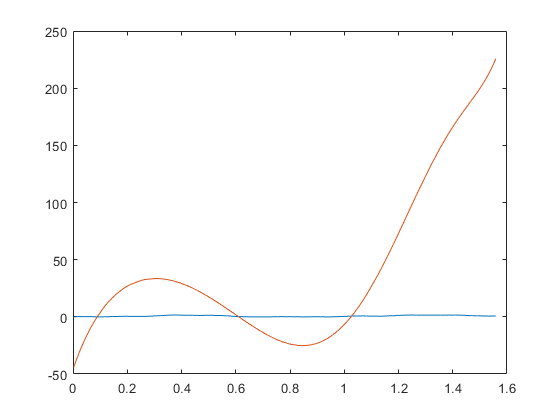




[B1,I] = sort(input(1:200));
B2 = output(I);

plot([B1 B1],[B2 a3(I)])


w1

w1 =    27.1638
 -313.1647
  699.5980
 -405.4784


w2

w2 =     8.2844
   -1.8017
   -0.0065
   -0.0000


ex= 0:10

ex =      0     1     2     3     4     5     6     7     8     9    10



% www = pinv(input.^ex)*(output);
www = pinv([sin(input).^2 cos(input).^2])*(output);


[B1,I] = sort(input);
B2 = output(I);

% recon = input.^ex*www
recon = [sin(input).^2 cos(input).^2]*www

recon =     0.9226
    0.8438
    0.5303
    0.9368
    0.8493
    0.4771
    0.8581
    0.6613
    0.4798
    0.7576


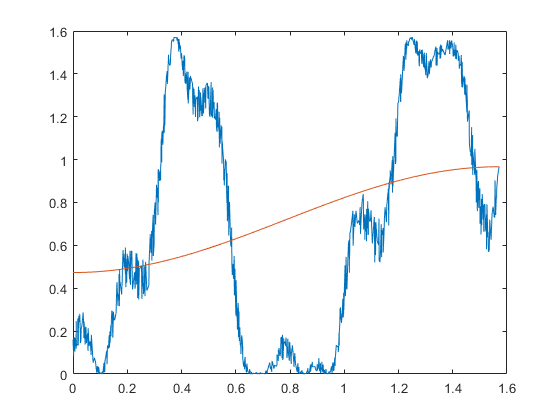



plot([B1 B1],[B2 recon(I)])


rataa = norm(recon-output)/norm(output)

rataa = 0.5832